## Computer Project 2: Simple OFDM Transmitter and Receiver

### EC4745 Wireless Mobile Ad Hoc Networking

Xisen Tian & Alex Schacht

## Part a

rng(1);     %make repeatable random numbers
m = 4; L1 = 16; L2=64; N=100; 

n = 1;  p = 0.5; 
bk1 = binornd(n, p, [m, L1, N]);
bk2 = binornd(n, p, [m, L2, N]);



## Part b


M = 16; 
%transform bk1, a m-L1-N array, into decimal values (0, 1, 2, ... 15)
bk1_2d = reshape(bk1, [m L1*N]);        %reshape the 3D binary array into 2D vector (bit-symbols are columns)
bk2_2d = reshape(bk2, [m L2*N]);        %reshape the 3D binary array into 2D vector (bit-symbols are columns)


mk1 = bi2de(bk1_2d', 'left-msb');        %bi2de expects row-vector binary values, so we transpose our column-vectors
mk2 = bi2de(bk2_2d', 'left-msb');        %bi2de expects row-vector binary values, so we transpose our column-vectors

%map the bit groupings to 16-QAM symbol constellations
xk1 = arrayfun(@(x) symToConst(x), mk1); 
xk2 = arrayfun(@(x) symToConst(x), mk2);


## Part c-d

%use the QAM signals to transmit through the fade channel 
qamvals = [3 1; 1 1; 3 3; 1 3; -3 1; -1 1; -3 3; -1 3; 3 -1; 1 -1; 3 -3;  1 -3; -3 -1; -1 -1; -3 -3; -1 -3]; 

%apply IFFT to the QAM frames 
xk1_2d = reshape(xk1, [L1 N]); xk2_2d = reshape(xk2, [L2 N]);
sk1 = ifft(xk1_2d); sk2 = ifft(xk2_2d ); 


%send the signals, once without ofdm, once with ofdm 
sigma = 0.4; 

ofdm_sig1 = fadeChannel(reshape(sk1, [1 L1*N]), sigma); 
sig1 = fadeChannel(reshape(xk1_2d, [1 L1*N]),sigma);            %16-QAM Signal w/out OFDM
ofdm_sig2 = fadeChannel(reshape(sk2, [1 L2*N]), sigma);       
sig2 = fadeChannel(reshape(xk2_2d, [1 L2*N]),sigma);            %64-QAM Signal w/out OFDM

% Recover the received signal
raw_ofdm1 = reshape(fft(reshape(ofdm_sig1, [L1 N])), [1 L1*N]); 
ofdm1_components = [real(raw_ofdm1); imag(raw_ofdm1)]; 

rec_symbols1 = [real(sig1); imag(sig1)];


raw_ofdm2 = reshape(fft(reshape(ofdm_sig2, [L2 N])), [1 L2*N]); 
ofdm2_components = [real(raw_ofdm2); imag(raw_ofdm2)]; 

rec_symbols2 = [real(sig2); imag(sig2)];


%do a knnsearch on the received symbols (minus 1 because qamvals start from
% 0 but the knnsearch outputs symbol indices counting from 1)
rec_ofdm1 = knnsearch(qamvals, ofdm1_components') - 1; 
rec_symbols1 = knnsearch(qamvals, rec_symbols1') - 1;

rec_ofdm2 = knnsearch(qamvals, ofdm2_components') - 1; 
rec_symbols2 = knnsearch(qamvals, rec_symbols2') - 1;


%calculate the bit errors 
r_msg_ofdm1 = de2bi(reshape(rec_ofdm1, [L1 N]), 'left-msb')';   
berr1ofdm = abs(sum(r_msg_ofdm1 - bk1_2d, 'all')) ./ (m*L1*N)

berr1ofdm = 0.0078


r_msg1 = de2bi(reshape(rec_symbols1, [L1 N]), 'left-msb')'; 
berr1 = abs(sum(r_msg1 - bk1_2d, 'all')) ./ (m*L1*N)

berr1 = 0.0041


r_msg_ofdm2 = de2bi(reshape(rec_ofdm2, [L2 N]), 'left-msb')'; 
berr2ofdm = abs(sum(r_msg_ofdm2 - bk2_2d, 'all')) ./ (m*L2*N)

berr2ofdm = 0.0035


r_msg2 = de2bi(reshape(rec_symbols2, [L2 N]), 'left-msb')'; 
berr2 = abs(sum(r_msg2 - bk2_2d, 'all')) ./ (m*L2*N)

berr2 = 3.5156e-04



sprintf('%d \t %d \t%d', [berr1, berr1ofdm, berr2ofdm])

ans = '4.062500e-03 	 7.812500e-03 	3.515625e-03'

## Plotting Original vs Received Signals

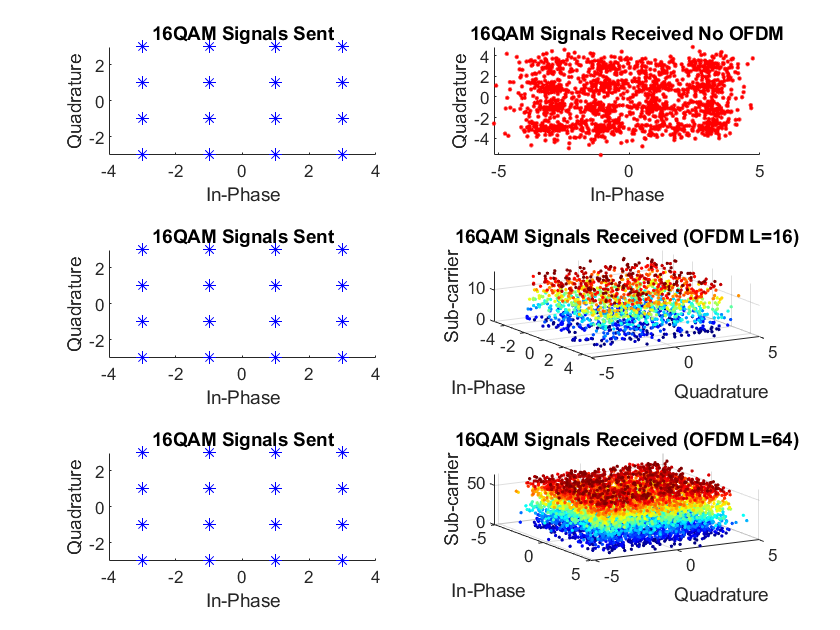

tiledlayout(3, 2)

%16QAM No OFDM
nexttile
scatter(real(xk1), imag(xk1), "blue", '*')
title('16QAM Signals Sent'); 
ylabel('Quadrature')
xlabel('In-Phase')

nexttile
scatter(real(sig1), imag(sig1), "red", '.')
title('16QAM Signals Received No OFDM'); 
ylabel('Quadrature')
xlabel('In-Phase')

%16QAM OFDM L=16
nexttile
scatter(real(xk1), imag(xk1), "blue", '*')
title('16QAM Signals Sent'); 
ylabel('Quadrature')
xlabel('In-Phase')

%reshape the symbols in 3d to visualize effects of subchannels 
raw_ofdm1_3d = reshape(raw_ofdm1, [L1 N]);      % each row is a subcarrier channel
raw_ofdm2_3d = reshape(raw_ofdm2, [L2 N]);      % each row is a subcarrier channel
getFrame = @(arr, x) arr(x,:);                  % get an OFDM subcarrier frame (used in 3d plotting)
z1 = [1:L1]; z2=[1:L2];                         % The z component to feed to getFrame
z1s = repmat(z1', [1, N]); z2s = repmat(z2', [1,N]);    % The z component used to graph 

%shape the x y and z vectors appropriately
X1 = real(getFrame(raw_ofdm1_3d, z1)); X2 = real(getFrame(raw_ofdm2_3d, z2)); 
Y1= imag(getFrame(raw_ofdm1_3d, z1)); Y2= imag(getFrame(raw_ofdm2_3d, z2)); 
z1r = reshape(z1s, [1, N*L1]); x1r = reshape(X1, [1, N*L1]); y1r = reshape(Y1, [1, N*L1]); 
z2r = reshape(z2s, [1, N*L2]); x2r = reshape(X2, [1, N*L2]); y2r = reshape(Y2, [1, N*L2]); 
%get color maps for each point in the scatter plot
S1 = repmat([3],numel(x1r),1);  % shapes
S2 = repmat([3],numel(x2r),1); 
c1 = z1r; c2=z2r; 
%c1 = 1:numel(z1s);      %# colors
%h1 = surface(X1, Y1, z1s, 'EdgeColor','flat');



nexttile
%scatter3(real(getFrame(raw_ofdm1_3d, z1)), imag(getFrame(raw_ofdm1_3d, z1)), z1s, "red", '+')
scatter3(x1r, y1r, z1r, S1, c1, 'filled')
%colormap( jet(numel(z1r)) )
title('16QAM Signals Received (OFDM L=16)'); 
ylabel('Quadrature')
xlabel('In-Phase')
zlabel('Sub-carrier')
view(60,40);

%16QAM OFDM L=64
nexttile
scatter(real(xk2), imag(xk2), "blue", '*')
title('16QAM Signals Sent'); 
ylabel('Quadrature')
xlabel('In-Phase')

nexttile
%scatter(real(raw_ofdm2), imag(raw_ofdm2), "red", '+')
scatter3(x2r, y2r, z2r, S2, c2, 'filled')
title('16QAM Signals Received (OFDM L=64)'); 
ylabel('Quadrature')
xlabel('In-Phase')
zlabel('Sub-carrier')
view(60,40);
hold off; 

## Functions Used

function constVal = symToConst(sym)
   switch sym
       case 0
           constVal = 3+1j; 
       case 1
           constVal = 1+1j; 
       case 2
           constVal = 3+3j; 
       case 3
           constVal = 1+3j;
       case 4
           constVal = -3+1j;
       case 5
           constVal = -1+1j; 
       case 6
           constVal = -3+3j; 
       case 7
           constVal = -1+3j;
       case 8
           constVal = 3-1j;
       case 9
           constVal = 1 -1j; 
       case 10
           constVal = 3-3j; 
       case 11
           constVal = 1-3j;
       case 12
           constVal = -3-1j;
       case 13
           constVal = -1-1j; 
       case 14
           constVal =  -3-3j;
       otherwise
           constVal = -1-3j;
   end
end

function sym = constToSym(const)
   switch const
       case 3+1j
           sym = 0; 
       case 1+1j
           sym = 1; 
       case 3+3j
           sym = 2; 
       case 1+3j
           sym = 3;
       case -3+1j
           sym = 4;
       case -1+1j
           sym = 5; 
       case -3+3j
           sym = 6; 
       case -1+3j
           sym = 7;
       case 3-1j
           sym = 8;
       case 1 -1j
           sym = 9; 
       case 3-3j
           sym = 10; 
       case  1-3j
           sym =11;
       case -3-1j
           sym = 12;
       case -1-1j
           sym =13; 
       case -3-3j
           sym = 14;
       otherwise
           sym = 15;
   end
end

function c = sym2const(s)
    qamvals = [3+1j 1+1j 3+3j 1+3j -3+1j -1+1j -3+3j -1+3j 3-1j 1 -1j 3-3j  1-3j -3-1j -1-1j -3-3j -1-3j]; 
    c = find(qamvals == s) - 1;
end

function s = const2sym(s)
    qamvals = [3+1j 1+1j 3+3j 1+3j -3+1j -1+1j -3+3j -1+3j 3-1j 1 -1j 3-3j  1-3j -3-1j -1-1j -3-3j -1-3j]; 
    s = qamvals(s+1);
end

function y = fadeChannel(xarr, sigma)
    l = length(xarr);
    a_mag = raylrnd(sigma, [1, l]);   %create the complex coefficient 'a' using a rayleigh distribution
    theta = (2*pi).*rand([1, l]);     %create theta based on uniform distribution
    expTheta = exp(-1j.*theta);
    a_vec = a_mag .* expTheta;     % enumerate the a values in a list
    
    y = zeros([1, l]); 
    y(1) = xarr(1); 
    for n = 2:1:l
        y(n) = xarr(n) + a_vec(n).*xarr(n-1); 
    end
end